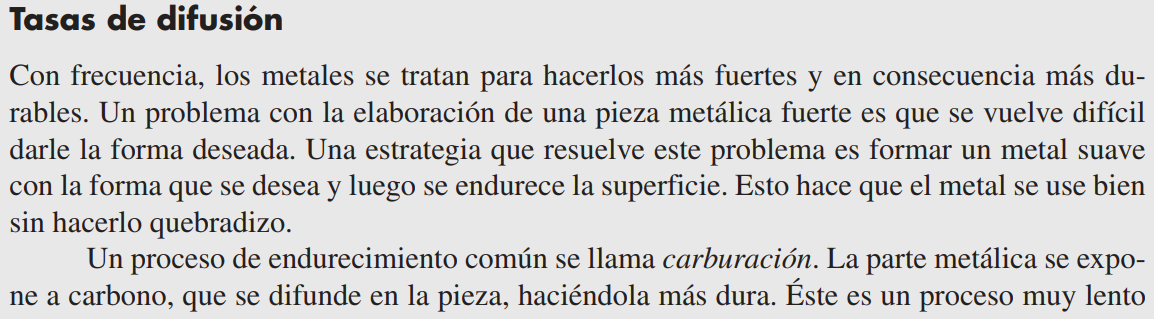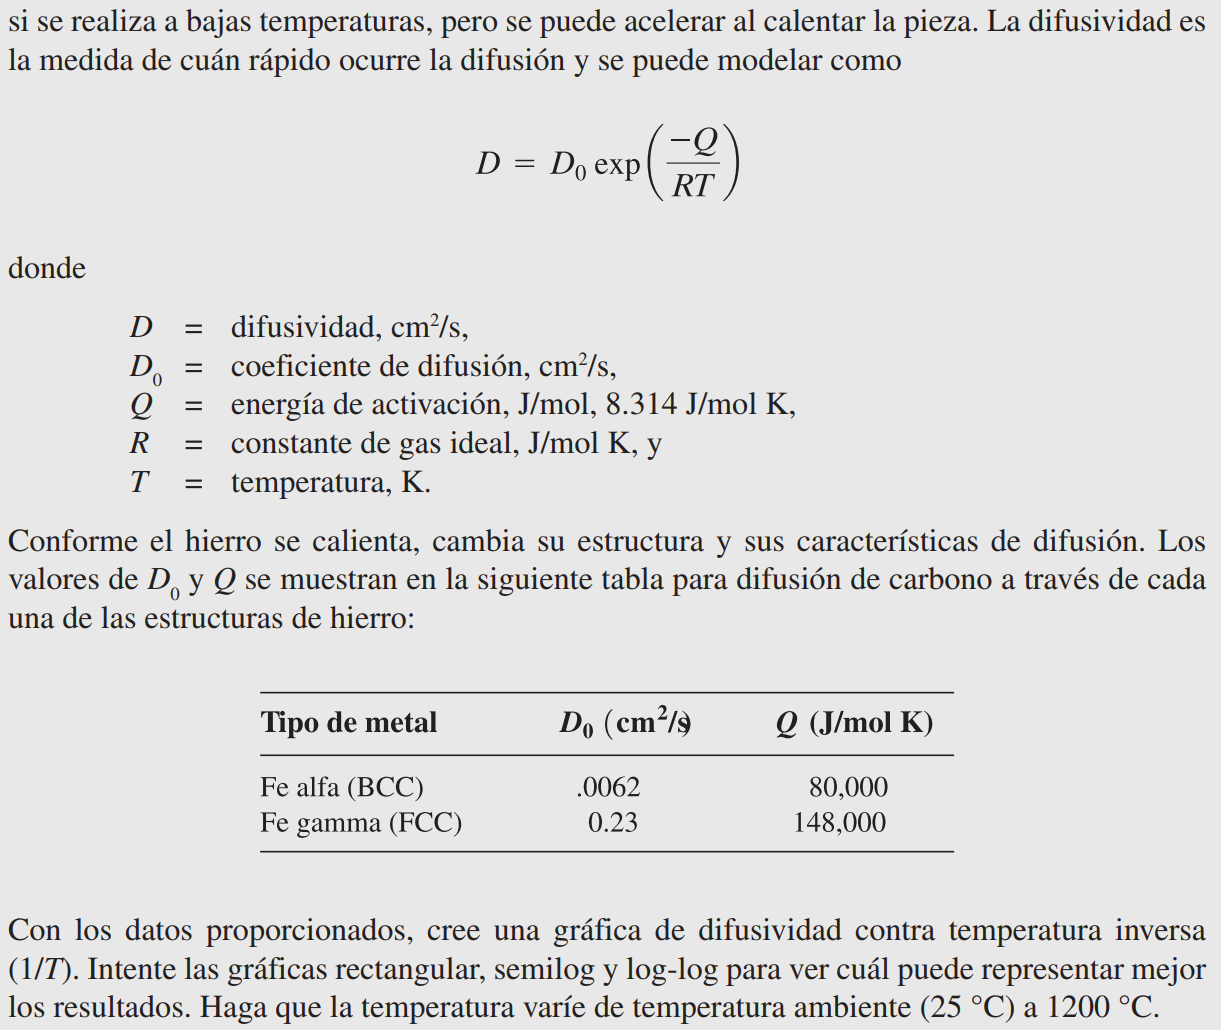

% Definir lo que se conoce.
clear

R = 8.314;
T = 298.15:20:1473.5;

% Para Fe alfa (BCC).
D0_alpha = .0062;
Q_alpha = 80e3;

% Para Fe gamma (FCC).
D0_gamma = .23;
Q_gamma = 148e3;

% Determinar la expresión de la difusividad.
% Para Fe alfa (BCC).
D_alpha = D0_alpha*exp(-Q_alpha./(R*T));

% Para Fe gamma (FCC).
D_gamma = D0_gamma*exp(-Q_gamma./(R*T));

% Gráficas.
D = [D_alpha; D_gamma];

subplot(2,2,1)
    plot(1./T,D)
    title 'Difusividad de C en Fe'
    ylabel 'Difusividad (cm^{2}/s)'
    legend('Fe alfa (BCC)','Fe gamma (FCC)')
    grid

subplot(2,2,2)
    loglog(1./T,D)
    title 'Difusividad de C en Fe'
    ylabel 'Difusividad (cm^{2}/s)'
    grid

subplot(2,2,3)
    semilogx(1./T,D)
    title 'Difusividad de C en Fe'
    xlabel 'Temperatura inversa (K^{-1})'
    ylabel 'Difusividad (cm^{2}/s)'
    grid

subplot(2,2,4)
    semilogy(1./T,D)
    title 'Difusividad de C en Fe'
    xlabel 'Temperatura inversa (K^{-1})'
    ylabel 'Difusividad (cm^{2}/s)'
    grid

La que representa mejor la temperatura es la gráfica lineal/log, es decir, la gráfica 4.